# MSI-x Part 2:wba-group E-untarget

- press the "Run" icon in the Liver Editor to implement all following code automatically.

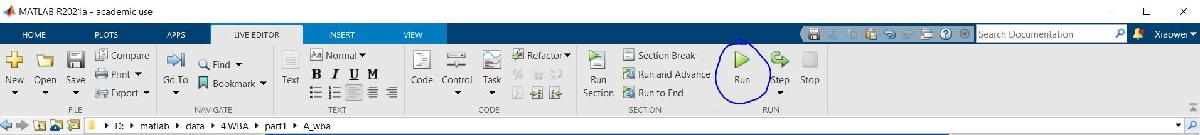

- The part 2 code aims to generate a group E-specific "pk_stata" for PDR/SNR statistics in the code in part 2, and data structure "structureE" for a follow-up run by the code in part 3.

- The whole run time is about 5 minutes.

## Step 1.Import CDF Files and save as a peaklist

% For demonstration: directly load the demo data
addpath 'D:\matlab\data\MSI(x)\part2\wba\E_wba'
load("subpeaklistE1.mat")
load("subpeaklistE2.mat")
load('cmz_neg.mat')
load("cmz_pos.mat")
load('roi_E.mat')

peaklist=[subpeaklist1;subpeaklist2];
clear subpeaklist1 subpeaklist2
clc

% specify parameters
% mass tolerance was set at 0.005 for binning peaks
tolerance=0.005;
% set the snr threshold at 1.5 and pdr threshold at 0.01 (1%)
thres_snr=1.5;
thres_pdr=0.01;

% Convert the profile MS data into centroid MS data
% Only preserve each peak's m/z and corresponding intensity values to save the storage
for i=1:length(peaklist)
    for j=1:length(peaklist{i})
        temp=peaklist{i,1}{j,1};
        peaklist{i,1}{j,1}=profile2centroid(temp);
    end
end
clear i j temp
clc

% separate the positive and negative channel for further data processing,
% respectively
for i=1:length(peaklist)
   peaklist_neg{i,1}=peaklist{i,1}(1:3:end,1); 
   peaklist_pos{i,1}=peaklist{i,1}(2:3:end,1);
end
clear i
clc

## Step 3-4.Construct a datacube and reduce its volume size

% construct the positive and negative datacube 
% Channel1: negative Full MS; Channel2: positive Full MS;
% This step takes around 4-5 minutes in total
datacube_neg=batchmassimage(peaklist_neg,cmz_neg,tolerance);

iter = 1

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 16

iter = 17

iter = 18

iter = 19

iter = 20

iter = 21

iter = 22

iter = 23

iter = 24

iter = 25

iter = 26

iter = 27

iter = 28

iter = 29

iter = 30

iter = 31

iter = 32

iter = 33

iter = 34

iter = 35

iter = 36

iter = 37

iter = 38

iter = 39

iter = 40

iter = 41

iter = 42

iter = 43

iter = 44

iter = 45

iter = 46

iter = 47

iter = 48

iter = 49

iter = 50

iter = 51

iter = 52

iter = 53

iter = 54

iter = 55

iter = 56

iter = 57

iter = 58

iter = 59

iter = 60

iter = 61

iter = 62

iter = 63

iter = 64

iter = 65

iter = 66

iter = 67

iter = 68

iter = 69

iter = 70

iter = 71

iter = 72

iter = 73

iter = 74

iter = 75

iter = 76

iter = 77

iter = 78

iter = 79

iter = 80

iter = 81

iter = 82

iter = 83

iter = 84

iter = 85

iter = 86

iter = 87

iter = 88

iter = 89

iter = 90

iter = 91

iter = 92

iter = 93

iter = 94

iter = 95

iter = 96

iter = 97

iter = 98

iter = 99

iter = 100

iter = 101

iter = 102

iter = 103

iter = 104

iter = 105

iter = 106

iter = 107

iter = 108

iter = 109

iter = 110

iter = 111

iter = 112

iter = 113

iter = 114

iter = 115

iter = 116

iter = 117

iter = 118

iter = 119

iter = 120

iter = 121

iter = 122

iter = 123

iter = 124

iter = 125

iter = 126

iter = 127

iter = 128

iter = 129

iter = 130

iter = 131

iter = 132

iter = 133

iter = 134

iter = 135

iter = 136

iter = 137

iter = 138

iter = 139

iter = 140

iter = 141

iter = 142

iter = 143

iter = 144

iter = 145

iter = 146

iter = 147

iter = 148

iter = 149

iter = 150

iter = 151

iter = 152

iter = 153

iter = 154

iter = 155

iter = 156

iter = 157

iter = 158

iter = 159

iter = 160

iter = 161

iter = 162

iter = 163

iter = 164

iter = 165

iter = 166

iter = 167

iter = 168

iter = 169

iter = 170

iter = 171

iter = 172

iter = 173

iter = 174

iter = 175

iter = 176

iter = 177

iter = 178

iter = 179

iter = 180

iter = 181

iter = 182

iter = 183

iter = 184

iter = 185

iter = 186

iter = 187

iter = 188

iter = 189

iter = 190

iter = 191

iter = 192

iter = 193

iter = 194

iter = 195

iter = 196

iter = 197

iter = 198

iter = 199

iter = 200

iter = 201

iter = 202

iter = 203

iter = 204

iter = 205

iter = 206

iter = 207

iter = 208

iter = 209

iter = 210

iter = 211

iter = 212

iter = 213

iter = 214

iter = 215

iter = 216

iter = 217

iter = 218

iter = 219

iter = 220

iter = 221

iter = 222

iter = 223

iter = 224

iter = 225

iter = 226

iter = 227

iter = 228

iter = 229

iter = 230

iter = 231

iter = 232

iter = 233

iter = 234

iter = 235

iter = 236

iter = 237

iter = 238

iter = 239

iter = 240

iter = 241

iter = 242

iter = 243

iter = 244

iter = 245

iter = 246

iter = 247

iter = 248

iter = 249

iter = 250

iter = 251

iter = 252

iter = 253

iter = 254

iter = 255

iter = 256

iter = 257

iter = 258

iter = 259

iter = 260

iter = 261

iter = 262

iter = 263

iter = 264

iter = 265

iter = 266

iter = 267

iter = 268

iter = 269

iter = 270

iter = 271

iter = 272

iter = 273

iter = 274

iter = 275

iter = 276

iter = 277

iter = 278

iter = 279

iter = 280

iter = 281

iter = 282

iter = 283

iter = 284

iter = 285

iter = 286

iter = 287

iter = 288

iter = 289

iter = 290

iter = 291

iter = 292

iter = 293

iter = 294

iter = 295

iter = 296

iter = 297

iter = 298

iter = 299

iter = 300

iter = 301

iter = 302

iter = 303

iter = 304

iter = 305

iter = 306

iter = 307

iter = 308

iter = 309

iter = 310

iter = 311

iter = 312

iter = 313

iter = 314

iter = 315

iter = 316

iter = 317

iter = 318

iter = 319

iter = 320

iter = 321

iter = 322

iter = 323

iter = 324

iter = 325

iter = 326

iter = 327

iter = 328

iter = 329

iter = 330

iter = 331

iter = 332

iter = 333

iter = 334

iter = 335

iter = 336

iter = 337

iter = 338

iter = 339

iter = 340

iter = 341

iter = 342

iter = 343

iter = 344

iter = 345

iter = 346

iter = 347

iter = 348

iter = 349

iter = 350

iter = 351

iter = 352

iter = 353

iter = 354

iter = 355

iter = 356

iter = 357

iter = 358

iter = 359

iter = 360

iter = 361

iter = 362

iter = 363

iter = 364

iter = 365

iter = 366

iter = 367

iter = 368

iter = 369

iter = 370

iter = 371

iter = 372

iter = 373

iter = 374

iter = 375

iter = 376

iter = 377

iter = 378

iter = 379

iter = 380

iter = 381

iter = 382

iter = 383

iter = 384

iter = 385

iter = 386

iter = 387

iter = 388

iter = 389

iter = 390

iter = 391

iter = 392

iter = 393

iter = 394

iter = 395

iter = 396

iter = 397

iter = 398

iter = 399

iter = 400

iter = 401

iter = 402

iter = 403

iter = 404

iter = 405

iter = 406

iter = 407

iter = 408

iter = 409

iter = 410

iter = 411

iter = 412

iter = 413

iter = 414

iter = 415

iter = 416

iter = 417

iter = 418

iter = 419

iter = 420

iter = 421

iter = 422

iter = 423

iter = 424

iter = 425

iter = 426

iter = 427

iter = 428

iter = 429

iter = 430

iter = 431

iter = 432

iter = 433

iter = 434

iter = 435

iter = 436

iter = 437

iter = 438

iter = 439

iter = 440

iter = 441

iter = 442

iter = 443

iter = 444

iter = 445

iter = 446

iter = 447

iter = 448

iter = 449

iter = 450

iter = 451

iter = 452

iter = 453

iter = 454

iter = 455

iter = 456

iter = 457

iter = 458

iter = 459

iter = 460

iter = 461

iter = 462

iter = 463

iter = 464

iter = 465

iter = 466

iter = 467

iter = 468

iter = 469

iter = 470

iter = 471

iter = 472

iter = 473

iter = 474

iter = 475

iter = 476

iter = 477

iter = 478

iter = 479

iter = 480

iter = 481

iter = 482

iter = 483

iter = 484

iter = 485

iter = 486

iter = 487

iter = 488

iter = 489

iter = 490

iter = 491

iter = 492

iter = 493

iter = 494

iter = 495

iter = 496

iter = 497

iter = 498

iter = 499

iter = 500

iter = 501

iter = 502

iter = 503

iter = 504

iter = 505

iter = 506

iter = 507

iter = 508

iter = 509

iter = 510

iter = 511

iter = 512

iter = 513

iter = 514

iter = 515

iter = 516

iter = 517

iter = 518

iter = 519

iter = 520

iter = 521

iter = 522

iter = 523

iter = 524

iter = 525

iter = 526

iter = 527

iter = 528

iter = 529

iter = 530

iter = 531

iter = 532

iter = 533

iter = 534

iter = 535

iter = 536

iter = 537

iter = 538

iter = 539

iter = 540

iter = 541

iter = 542

iter = 543

iter = 544

iter = 545

iter = 546

iter = 547

iter = 548

iter = 549

iter = 550

iter = 551

iter = 552

iter = 553

iter = 554

iter = 555

iter = 556

iter = 557

iter = 558

iter = 559

iter = 560

iter = 561

iter = 562

iter = 563

iter = 564

iter = 565

iter = 566

iter = 567

iter = 568

iter = 569

iter = 570

iter = 571

iter = 572

iter = 573

iter = 574

iter = 575

iter = 576

iter = 577

iter = 578

iter = 579

iter = 580

iter = 581

iter = 582

iter = 583

iter = 584

iter = 585

iter = 586

iter = 587

iter = 588

iter = 589

iter = 590

iter = 591

iter = 592

iter = 593

iter = 594

iter = 595

iter = 596

iter = 597

iter = 598

iter = 599

iter = 600

iter = 601

iter = 602

iter = 603

iter = 604

iter = 605

iter = 606

iter = 607

iter = 608

iter = 609

iter = 610

iter = 611

iter = 612

iter = 613

iter = 614

iter = 615

iter = 616

iter = 617

iter = 618

iter = 619

iter = 620

iter = 621

iter = 622

iter = 623

iter = 624

iter = 625

iter = 626

iter = 627

iter = 628

iter = 629

iter = 630

iter = 631

iter = 632

iter = 633

iter = 634

iter = 635

iter = 636

iter = 637

iter = 638

iter = 639

iter = 640

iter = 641

iter = 642

iter = 643

iter = 644

iter = 645

iter = 646

iter = 647

iter = 648

iter = 649

iter = 650

iter = 651

iter = 652

iter = 653

iter = 654

iter = 655

iter = 656

iter = 657

iter = 658

iter = 659

iter = 660

iter = 661

iter = 662

iter = 663

iter = 664

iter = 665

iter = 666

iter = 667

iter = 668

iter = 669

iter = 670

iter = 671

iter = 672

iter = 673

iter = 674

iter = 675

iter = 676

iter = 677

iter = 678

iter = 679

iter = 680

iter = 681

iter = 682

iter = 683

iter = 684

iter = 685

iter = 686

iter = 687

iter = 688

iter = 689

iter = 690

iter = 691

iter = 692

iter = 693

iter = 694

iter = 695

iter = 696

iter = 697

iter = 698

iter = 699

iter = 700

iter = 701

iter = 702

iter = 703

iter = 704

iter = 705

iter = 706

iter = 707

iter = 708

iter = 709

iter = 710

iter = 711

iter = 712

iter = 713

iter = 714

iter = 715

iter = 716

iter = 717

iter = 718

iter = 719

iter = 720

iter = 721

iter = 722

iter = 723

iter = 724

iter = 725

iter = 726

iter = 727

iter = 728

iter = 729

iter = 730

iter = 731

iter = 732

iter = 733

iter = 734

iter = 735

iter = 736

iter = 737

iter = 738

iter = 739

iter = 740

iter = 741

iter = 742

iter = 743

iter = 744

iter = 745

iter = 746

iter = 747

iter = 748

iter = 749

iter = 750

iter = 751

iter = 752

iter = 753

iter = 754

iter = 755

iter = 756

iter = 757

iter = 758

iter = 759

iter = 760

iter = 761

iter = 762

iter = 763

iter = 764

iter = 765

iter = 766

iter = 767

iter = 768

iter = 769

iter = 770

iter = 771

iter = 772

iter = 773

iter = 774

iter = 775

iter = 776

iter = 777

iter = 778

iter = 779

iter = 780

iter = 781

iter = 782

iter = 783

iter = 784

iter = 785

iter = 786

iter = 787

iter = 788

iter = 789

iter = 790

iter = 791

iter = 792

iter = 793

iter = 794

iter = 795

iter = 796

iter = 797

iter = 798

iter = 799

iter = 800

iter = 801

iter = 802

iter = 803

iter = 804

iter = 805

iter = 806

iter = 807

iter = 808

iter = 809

iter = 810

iter = 811

iter = 812

iter = 813

iter = 814

iter = 815

iter = 816

iter = 817

iter = 818

iter = 819

iter = 820

iter = 821

iter = 822

iter = 823

iter = 824

iter = 825

iter = 826

iter = 827

iter = 828

iter = 829

iter = 830

iter = 831

iter = 832

iter = 833

iter = 834

iter = 835

iter = 836

iter = 837

iter = 838

iter = 839

iter = 840

iter = 841

iter = 842

iter = 843

iter = 844

iter = 845

iter = 846

iter = 847

iter = 848

iter = 849

iter = 850

iter = 851

iter = 852

iter = 853

iter = 854

iter = 855

iter = 856

iter = 857

iter = 858

iter = 859

iter = 860

iter = 861

iter = 862

iter = 863

iter = 864

iter = 865

iter = 866

iter = 867

iter = 868

iter = 869

iter = 870

iter = 871

iter = 872

iter = 873

iter = 874

iter = 875

iter = 876

iter = 877

iter = 878

iter = 879

iter = 880

iter = 881

iter = 882

iter = 883

iter = 884

iter = 885

iter = 886

iter = 887

iter = 888

iter = 889

iter = 890

iter = 891

iter = 892

iter = 893

iter = 894

iter = 895

iter = 896

iter = 897

iter = 898

iter = 899

iter = 900

iter = 901

iter = 902

iter = 903

iter = 904

iter = 905

iter = 906

iter = 907

iter = 908

iter = 909

iter = 910

iter = 911

iter = 912

iter = 913

iter = 914

iter = 915

iter = 916

iter = 917

iter = 918

iter = 919

iter = 920

iter = 921

iter = 922

iter = 923

iter = 924

iter = 925

iter = 926

iter = 927

iter = 928

iter = 929

iter = 930

iter = 931

iter = 932

iter = 933

iter = 934

iter = 935

iter = 936

iter = 937

iter = 938

iter = 939

iter = 940

iter = 941

iter = 942

iter = 943

iter = 944

iter = 945

iter = 946

iter = 947

iter = 948

iter = 949

iter = 950

iter = 951

iter = 952

iter = 953

iter = 954

iter = 955

iter = 956

iter = 957

iter = 958

iter = 959

iter = 960

iter = 961

iter = 962

iter = 963

iter = 964

iter = 965

iter = 966

iter = 967

iter = 968

iter = 969

iter = 970

iter = 971

iter = 972

iter = 973

iter = 974

iter = 975

iter = 976

iter = 977

iter = 978

iter = 979

iter = 980

iter = 981

iter = 982

iter = 983

iter = 984

iter = 985

iter = 986

iter = 987

iter = 988

iter = 989

iter = 990

iter = 991

iter = 992

iter = 993

iter = 994

iter = 995

iter = 996

iter = 997

iter = 998

iter = 999

iter = 1000

iter = 1001

iter = 1002

iter = 1003

iter = 1004

iter = 1005

iter = 1006

iter = 1007

iter = 1008

iter = 1009

iter = 1010

iter = 1011

iter = 1012

iter = 1013

iter = 1014

iter = 1015

iter = 1016

iter = 1017

iter = 1018

iter = 1019

iter = 1020

iter = 1021

iter = 1022

iter = 1023

iter = 1024

iter = 1025

iter = 1026

iter = 1027

iter = 1028

iter = 1029

iter = 1030

iter = 1031

iter = 1032

iter = 1033

iter = 1034

iter = 1035

iter = 1036

iter = 1037

iter = 1038

iter = 1039

iter = 1040

iter = 1041

iter = 1042

iter = 1043

iter = 1044

iter = 1045

iter = 1046

iter = 1047

iter = 1048

iter = 1049

iter = 1050

iter = 1051

iter = 1052

iter = 1053

iter = 1054

iter = 1055

iter = 1056

iter = 1057

iter = 1058

iter = 1059

iter = 1060

iter = 1061

iter = 1062

iter = 1063

iter = 1064

iter = 1065

iter = 1066

iter = 1067

iter = 1068

iter = 1069

iter = 1070

iter = 1071

iter = 1072

iter = 1073

iter = 1074

iter = 1075

iter = 1076

iter = 1077

iter = 1078

iter = 1079

iter = 1080

iter = 1081

iter = 1082

iter = 1083

iter = 1084

iter = 1085

iter = 1086

iter = 1087

iter = 1088

iter = 1089

iter = 1090

iter = 1091

iter = 1092

iter = 1093

iter = 1094

iter = 1095

iter = 1096

iter = 1097

iter = 1098

iter = 1099

iter = 1100

iter = 1101

iter = 1102

iter = 1103

iter = 1104

iter = 1105

iter = 1106

iter = 1107

iter = 1108

iter = 1109

iter = 1110

iter = 1111

iter = 1112

iter = 1113

iter = 1114

iter = 1115

iter = 1116

iter = 1117

iter = 1118

iter = 1119

iter = 1120

iter = 1121

iter = 1122

iter = 1123

iter = 1124

iter = 1125

iter = 1126

iter = 1127

iter = 1128

iter = 1129

iter = 1130

iter = 1131

iter = 1132

iter = 1133

iter = 1134

iter = 1135

iter = 1136

iter = 1137

iter = 1138

iter = 1139

iter = 1140

iter = 1141

iter = 1142

iter = 1143

iter = 1144

iter = 1145

iter = 1146

iter = 1147

iter = 1148

iter = 1149

iter = 1150

iter = 1151

iter = 1152

iter = 1153

iter = 1154

iter = 1155

iter = 1156

iter = 1157

iter = 1158

iter = 1159

iter = 1160

iter = 1161

iter = 1162

iter = 1163

iter = 1164

iter = 1165

iter = 1166

iter = 1167

iter = 1168

iter = 1169

iter = 1170

iter = 1171

iter = 1172

iter = 1173

iter = 1174

iter = 1175

iter = 1176

iter = 1177

iter = 1178

iter = 1179

iter = 1180

iter = 1181

iter = 1182

iter = 1183

iter = 1184

iter = 1185

iter = 1186

iter = 1187

iter = 1188

iter = 1189

iter = 1190

iter = 1191

iter = 1192

iter = 1193

iter = 1194

iter = 1195

iter = 1196

iter = 1197

iter = 1198

iter = 1199

iter = 1200

iter = 1201

iter = 1202

iter = 1203

iter = 1204

iter = 1205

iter = 1206

iter = 1207

iter = 1208

iter = 1209

iter = 1210

iter = 1211

iter = 1212

iter = 1213

iter = 1214

iter = 1215

iter = 1216

iter = 1217

iter = 1218

iter = 1219

iter = 1220

iter = 1221

iter = 1222

iter = 1223

iter = 1224

iter = 1225

iter = 1226

iter = 1227

iter = 1228

iter = 1229

iter = 1230

iter = 1231

iter = 1232

iter = 1233

iter = 1234

iter = 1235

iter = 1236

iter = 1237

iter = 1238

iter = 1239

iter = 1240

iter = 1241

iter = 1242

iter = 1243

iter = 1244

iter = 1245

iter = 1246

iter = 1247

iter = 1248

iter = 1249

iter = 1250

iter = 1251

iter = 1252

iter = 1253

iter = 1254

iter = 1255

iter = 1256

iter = 1257

iter = 1258

iter = 1259

iter = 1260

iter = 1261

iter = 1262

iter = 1263

iter = 1264

iter = 1265

iter = 1266

iter = 1267

iter = 1268

iter = 1269

iter = 1270

iter = 1271

iter = 1272

iter = 1273

iter = 1274

iter = 1275

iter = 1276

iter = 1277

iter = 1278

iter = 1279

iter = 1280

iter = 1281

iter = 1282

iter = 1283

iter = 1284

iter = 1285

iter = 1286

iter = 1287

iter = 1288

iter = 1289

iter = 1290

iter = 1291

iter = 1292

iter = 1293

iter = 1294

iter = 1295

iter = 1296

iter = 1297

iter = 1298

iter = 1299

iter = 1300

iter = 1301

iter = 1302

iter = 1303

iter = 1304

iter = 1305

iter = 1306

iter = 1307

iter = 1308

iter = 1309

iter = 1310

iter = 1311

iter = 1312

iter = 1313

iter = 1314

iter = 1315

iter = 1316

iter = 1317

iter = 1318

iter = 1319

iter = 1320

iter = 1321

iter = 1322

iter = 1323

iter = 1324

iter = 1325

iter = 1326

iter = 1327

iter = 1328

iter = 1329

iter = 1330

iter = 1331

iter = 1332

iter = 1333

iter = 1334

iter = 1335

iter = 1336

iter = 1337

iter = 1338

iter = 1339

iter = 1340

iter = 1341

iter = 1342

iter = 1343

iter = 1344

iter = 1345

iter = 1346

iter = 1347

iter = 1348

iter = 1349

iter = 1350

iter = 1351

iter = 1352

iter = 1353

iter = 1354

iter = 1355

iter = 1356

iter = 1357

iter = 1358

iter = 1359

iter = 1360

iter = 1361

iter = 1362

iter = 1363

iter = 1364

iter = 1365

iter = 1366

iter = 1367

iter = 1368

iter = 1369

iter = 1370

iter = 1371

iter = 1372

iter = 1373

iter = 1374

iter = 1375

iter = 1376

iter = 1377

iter = 1378

iter = 1379

iter = 1380

iter = 1381

iter = 1382

iter = 1383

iter = 1384

iter = 1385

iter = 1386

iter = 1387

iter = 1388

iter = 1389

iter = 1390

iter = 1391

iter = 1392

iter = 1393

iter = 1394

iter = 1395

iter = 1396

iter = 1397

iter = 1398

iter = 1399

iter = 1400

iter = 1401

iter = 1402

iter = 1403

iter = 1404

iter = 1405

iter = 1406

iter = 1407

iter = 1408

iter = 1409

iter = 1410

iter = 1411

iter = 1412

iter = 1413

iter = 1414

iter = 1415

iter = 1416

iter = 1417

iter = 1418

iter = 1419

iter = 1420

iter = 1421

iter = 1422

iter = 1423

iter = 1424

iter = 1425

iter = 1426

iter = 1427

iter = 1428

iter = 1429

iter = 1430

iter = 1431

iter = 1432

iter = 1433

iter = 1434

iter = 1435

iter = 1436

iter = 1437

iter = 1438

iter = 1439

iter = 1440

iter = 1441

iter = 1442

iter = 1443

iter = 1444

iter = 1445

iter = 1446

iter = 1447

iter = 1448

iter = 1449

iter = 1450

iter = 1451

iter = 1452

iter = 1453

iter = 1454

iter = 1455

iter = 1456

iter = 1457

iter = 1458

iter = 1459

iter = 1460

iter = 1461

iter = 1462

iter = 1463

iter = 1464

iter = 1465

iter = 1466

iter = 1467

iter = 1468

iter = 1469

iter = 1470

iter = 1471

iter = 1472

iter = 1473

iter = 1474

iter = 1475

iter = 1476

iter = 1477

iter = 1478

iter = 1479

iter = 1480

iter = 1481

iter = 1482

iter = 1483

iter = 1484

iter = 1485

iter = 1486

iter = 1487

iter = 1488

iter = 1489

iter = 1490

iter = 1491

iter = 1492

iter = 1493

iter = 1494

iter = 1495

iter = 1496

iter = 1497

iter = 1498

iter = 1499

iter = 1500

iter = 1501

iter = 1502

iter = 1503

iter = 1504

iter = 1505

iter = 1506

iter = 1507

iter = 1508

iter = 1509

iter = 1510

iter = 1511

iter = 1512

iter = 1513

iter = 1514

iter = 1515

iter = 1516

iter = 1517

iter = 1518

iter = 1519

iter = 1520

iter = 1521

iter = 1522

iter = 1523

iter = 1524

iter = 1525

iter = 1526

iter = 1527

iter = 1528

iter = 1529

iter = 1530

iter = 1531

iter = 1532

iter = 1533

iter = 1534

iter = 1535

iter = 1536

iter = 1537

iter = 1538

iter = 1539

iter = 1540

iter = 1541

iter = 1542

iter = 1543

iter = 1544

iter = 1545

iter = 1546

iter = 1547

iter = 1548

iter = 1549

iter = 1550

iter = 1551

iter = 1552

iter = 1553

iter = 1554

iter = 1555

iter = 1556

iter = 1557

iter = 1558

iter = 1559

iter = 1560

iter = 1561

iter = 1562

iter = 1563

iter = 1564

iter = 1565

iter = 1566

iter = 1567

iter = 1568

iter = 1569

iter = 1570

iter = 1571

iter = 1572

iter = 1573

iter = 1574

iter = 1575

iter = 1576

iter = 1577

iter = 1578

iter = 1579

iter = 1580

iter = 1581

iter = 1582

iter = 1583

iter = 1584

iter = 1585

iter = 1586

iter = 1587

iter = 1588

iter = 1589

iter = 1590

iter = 1591

iter = 1592

iter = 1593

iter = 1594

iter = 1595

iter = 1596

iter = 1597

iter = 1598

iter = 1599

iter = 1600

iter = 1601

iter = 1602

iter = 1603

iter = 1604

iter = 1605

iter = 1606

iter = 1607

iter = 1608

iter = 1609

iter = 1610

iter = 1611

iter = 1612

iter = 1613

iter = 1614

iter = 1615

iter = 1616

iter = 1617

iter = 1618

iter = 1619

iter = 1620

iter = 1621

iter = 1622

iter = 1623

iter = 1624

iter = 1625

iter = 1626

iter = 1627

iter = 1628

iter = 1629

iter = 1630

iter = 1631

iter = 1632

iter = 1633

iter = 1634

iter = 1635

iter = 1636

iter = 1637

iter = 1638

iter = 1639

iter = 1640

iter = 1641

iter = 1642

iter = 1643

iter = 1644

iter = 1645

iter = 1646

iter = 1647

iter = 1648

iter = 1649

iter = 1650

iter = 1651

iter = 1652

iter = 1653

iter = 1654

iter = 1655

iter = 1656

iter = 1657

iter = 1658

iter = 1659

iter = 1660

iter = 1661

iter = 1662

iter = 1663

iter = 1664

iter = 1665

iter = 1666

iter = 1667

iter = 1668

iter = 1669

iter = 1670

iter = 1671

iter = 1672

iter = 1673

iter = 1674

iter = 1675

iter = 1676

iter = 1677

iter = 1678

iter = 1679

iter = 1680

iter = 1681

iter = 1682

iter = 1683

iter = 1684

iter = 1685

iter = 1686

iter = 1687

iter = 1688

iter = 1689

iter = 1690

iter = 1691

iter = 1692

iter = 1693

iter = 1694

iter = 1695

iter = 1696

iter = 1697

iter = 1698

iter = 1699

iter = 1700

iter = 1701

iter = 1702

iter = 1703

iter = 1704

iter = 1705

iter = 1706

iter = 1707

iter = 1708

iter = 1709

iter = 1710

iter = 1711

iter = 1712

iter = 1713

iter = 1714

iter = 1715

iter = 1716

iter = 1717

iter = 1718

iter = 1719

iter = 1720

iter = 1721

iter = 1722

iter = 1723

iter = 1724

iter = 1725

iter = 1726

iter = 1727

iter = 1728

iter = 1729

iter = 1730

iter = 1731

iter = 1732

iter = 1733

iter = 1734

iter = 1735

iter = 1736

iter = 1737

iter = 1738

iter = 1739

iter = 1740

iter = 1741

iter = 1742

iter = 1743

iter = 1744

iter = 1745

iter = 1746

iter = 1747

iter = 1748

iter = 1749

iter = 1750

iter = 1751

iter = 1752

iter = 1753

iter = 1754

iter = 1755

iter = 1756

iter = 1757

iter = 1758

iter = 1759

iter = 1760

iter = 1761

iter = 1762

iter = 1763

iter = 1764

iter = 1765

iter = 1766

iter = 1767

iter = 1768

iter = 1769

iter = 1770

iter = 1771

iter = 1772

iter = 1773

iter = 1774

iter = 1775

iter = 1776

iter = 1777

iter = 1778

iter = 1779

iter = 1780

iter = 1781

iter = 1782

iter = 1783

iter = 1784

iter = 1785

iter = 1786

iter = 1787

iter = 1788

iter = 1789

iter = 1790

iter = 1791

iter = 1792

iter = 1793

iter = 1794

iter = 1795

iter = 1796

iter = 1797

iter = 1798

iter = 1799

iter = 1800

iter = 1801

iter = 1802

iter = 1803

iter = 1804

iter = 1805

iter = 1806

iter = 1807

iter = 1808

iter = 1809

iter = 1810

iter = 1811

iter = 1812

iter = 1813

iter = 1814

iter = 1815

iter = 1816

iter = 1817

iter = 1818

iter = 1819

iter = 1820

iter = 1821

iter = 1822

iter = 1823

iter = 1824

iter = 1825

iter = 1826

iter = 1827

iter = 1828

iter = 1829

iter = 1830

iter = 1831

iter = 1832

iter = 1833

iter = 1834

iter = 1835

iter = 1836

iter = 1837

iter = 1838

iter = 1839

iter = 1840

iter = 1841

iter = 1842

iter = 1843

iter = 1844

iter = 1845

iter = 1846

iter = 1847

iter = 1848

iter = 1849

iter = 1850

iter = 1851

iter = 1852

iter = 1853

iter = 1854

iter = 1855

iter = 1856

iter = 1857

iter = 1858

iter = 1859

iter = 1860

iter = 1861

iter = 1862

iter = 1863

iter = 1864

iter = 1865

iter = 1866

iter = 1867

iter = 1868

iter = 1869

iter = 1870

iter = 1871

iter = 1872

iter = 1873

iter = 1874

iter = 1875

iter = 1876

iter = 1877

iter = 1878

iter = 1879

iter = 1880

iter = 1881

iter = 1882

iter = 1883

iter = 1884

iter = 1885

iter = 1886

iter = 1887

iter = 1888

iter = 1889

iter = 1890

iter = 1891

iter = 1892

iter = 1893

iter = 1894

iter = 1895

iter = 1896

iter = 1897

iter = 1898

iter = 1899

iter = 1900

iter = 1901

iter = 1902

iter = 1903

iter = 1904

iter = 1905

iter = 1906

iter = 1907

iter = 1908

iter = 1909

iter = 1910

iter = 1911

iter = 1912

iter = 1913

iter = 1914

iter = 1915

iter = 1916

iter = 1917

iter = 1918

iter = 1919

iter = 1920

iter = 1921

iter = 1922

iter = 1923

iter = 1924

iter = 1925

iter = 1926

iter = 1927

iter = 1928

iter = 1929

iter = 1930

iter = 1931

iter = 1932

iter = 1933

iter = 1934

iter = 1935

iter = 1936

iter = 1937

iter = 1938

iter = 1939

iter = 1940

iter = 1941

iter = 1942

iter = 1943

iter = 1944

iter = 1945

iter = 1946

iter = 1947

iter = 1948

iter = 1949

iter = 1950

iter = 1951

iter = 1952

iter = 1953

iter = 1954

iter = 1955

iter = 1956

iter = 1957

iter = 1958

iter = 1959

iter = 1960

iter = 1961

iter = 1962

iter = 1963

iter = 1964

iter = 1965

iter = 1966

iter = 1967

iter = 1968

iter = 1969

iter = 1970

iter = 1971

iter = 1972

iter = 1973

iter = 1974

iter = 1975

iter = 1976

iter = 1977

iter = 1978

iter = 1979

iter = 1980

iter = 1981

iter = 1982

iter = 1983

iter = 1984

iter = 1985

iter = 1986

iter = 1987

iter = 1988

iter = 1989

iter = 1990

iter = 1991

iter = 1992

iter = 1993

iter = 1994

iter = 1995

iter = 1996

iter = 1997

iter = 1998

iter = 1999

iter = 2000

datacube_pos=batchmassimage(peaklist_pos,cmz_pos,tolerance);

Datacube Volume Reduction

- Reduce the matrix volume by excluding noise and background peaks.

- Positive detection rate (PDR) and signal-to-noise ratio (SNR) are used as metrics.

- PDR depicts the percentage of pixels that contain certain peak.

- SNR depicts the average intensity ratio of certain peak across the sample region(roi==1) and background region (roi==0).

% generate the roi pixels' index
[bio_r,bio_c]=find(roi==1);
biopix_indx=[bio_r,bio_c];
clear bio_r bio_c threshold landmarksum
clc

% for the negative datacube
% get the pdr and snr values of each peak in the datacube
for i=1:length(datacube_neg)
    cache=datacube_neg{i,2}(:);
    int_roi=mean(cache(roi(:)==1));
    int_bk=mean(cache(roi(:)==0));
    pdr_indx_neg(i,1)=nnz(cache(roi(:)==1))/nnz(roi(:));
    snr_indx_neg(i,1)=int_roi/int_bk;
end
clear i cache int_roi int_bk snr
clc

for i=1:length(datacube_pos)
    cache=datacube_pos{i,2}(:);
    int_roi=mean(cache(roi(:)==1));
    int_bk=mean(cache(roi(:)==0));
    pdr_indx_pos(i,1)=nnz(cache(roi(:)==1))/nnz(roi(:));
    snr_indx_pos(i,1)=int_roi/int_bk;
end
clear i cache int_roi int_bk snr
clc


% only preserve those peaks with the SNR and PDR higher than the setted threshold values
% the ion which has SNR less than 1.5 will be regarded as BK ions and removed.
% Group indx in tumor analysis: A=1,B=2,C=3,D=4,E=5,F=6,G=7
groupIndx=5;
for i=1:length(cmz_neg)
  if pdr_indx_neg(i)>=thres_pdr & snr_indx_neg(i)>=thres_snr
     pk_stata_neg(i,groupIndx)=1;
  else
     pk_stata_neg(i,groupIndx)=0;
  end
end
clear i
clc

for i=1:length(cmz_pos)
  if pdr_indx_pos(i)>=thres_pdr & snr_indx_pos(i)>=thres_snr
     pk_stata_pos(i,groupIndx)=1;
  else
     pk_stata_pos(i,groupIndx)=0;
  end
end
clear i
clc

NOTE: for sake of comparison, the final peak selection was selected according to the statstic analysis results of mass bins' PDR and SNR across the 7 (6) groups of samples.

% For demonstration, load the demo data for the pre-selected biopeak index
load("biopk_indx_neg.mat")
biocube_neg=datacube_neg(biopk_indx_neg,:);

load("biopk_indx_pos.mat")
biocube_pos=datacube_pos(biopk_indx_pos,:);

## Step 5.Convert a datacube to a biomatrix

- A biomatrix is composed of n rows-by- m columns.

- Each row represent a pixel within the sample region and each column represents a mass bin

% Conversion from datacube to biomatrix
for i=1:length(biocube_neg)
    temp=biocube_neg{i,2}(:);
    biomat_neg(:,i)=temp(find(roi==1));
end
clear i temp
clc

for i=1:length(biocube_pos)
    temp=biocube_pos{i,2}(:);
    biomat_pos(:,i)=temp(find(roi==1));
end
clear i temp
clc

% manually check if any column from the biomatrix can be reconstructed into an authentic image 
% for example 1: pos. m/z 104.1010, Choline, [M+H]+
imagesc(indximg(biomat_pos(:,25),biopix_indx(:,1),biopix_indx(:,2)));
% example 2: neg. m/z 303.2323 arachidonic acid，[M-H]-
figure(2)
imagesc(indximg(biomat_neg(:,519),biopix_indx(:,1),biopix_indx(:,2)));

## Step 7. Biomatrix splitting and regional biomatrix re-combination

% Create Group-based Structures
% Extract the region-specific pixels and corresponding sub-biomatrix
% for demonstration, load the precisely predicted label for the demo data group B
load("label_precise_E.mat")

% combine the positive and negative biomat together
biomat=[biomat_pos,biomat_neg];

% For  data (as control), create a structure "structureX" including all necessary data for the following analysis.
% The annotation "X" here should be replaced by B, C, D, E, F, and G by user when processing the corresponding data in the separate folder.
% specify the number of label by user accodring to a sample
% physiolgical nature. For wba, in this study case, it is divided into 15
% regions.
numOfLabel=15;
% construc a structure datatype variable
for i=1:numOfLabel
   structureE.regionBiomatArray{i,1}=biomat(label_precise==i,:);
   structureE.regionPixIndxArray{i,1}=biopix_indx(label_precise==i,:);
   structureE.regionPixNumber{i,1}=length(find(label_precise==i));
end
clear i numOfLabel
clc
structureE.regionLabel={'Heart';'Lung';'Spleen';'kidney';'brain';...
    'liver';'Gastric';'GI tract';'muscle';'thymus';'skin';...
    'gland';'Jaw';'GIT contents';'Bone'};
structureE.biopk=[cmz_pos(biopk_indx_pos);cmz_neg(biopk_indx_neg)];
structureE.comment={"biopk_pos+biopk_neg"};
% Likewise, create structured variable for group C, D, E, F, G data including all necessary information for the
% following analysis

save("pk_stata_neg_E","pk_stata_neg");
save("pk_stata_pos_E","pk_stata_pos");
save("structure_untarget_E.mat","structureE")